# FNN CNN LSTM - Get Data - for fast charge dataset

% clear

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-05-12_batchdata_updated_struct_errorcorrect.mat
trainDataOrg = batch;

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-06-30_batchdata_updated_struct_errorcorrect.mat
testData = batch;

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2018-04-12_batchdata_updated_struct_errorcorrect.mat
testData2 = batch;

clear batch
clear batch_date

### Feature Extraction

Discharge capacity is a key feature that can reflect the health of a battery, and its value is indicative of driving range in an electric vehicle. Plot discharge capacity for the first 1,000 cycles of cells in training data to visualize its change across the life of a cell.  

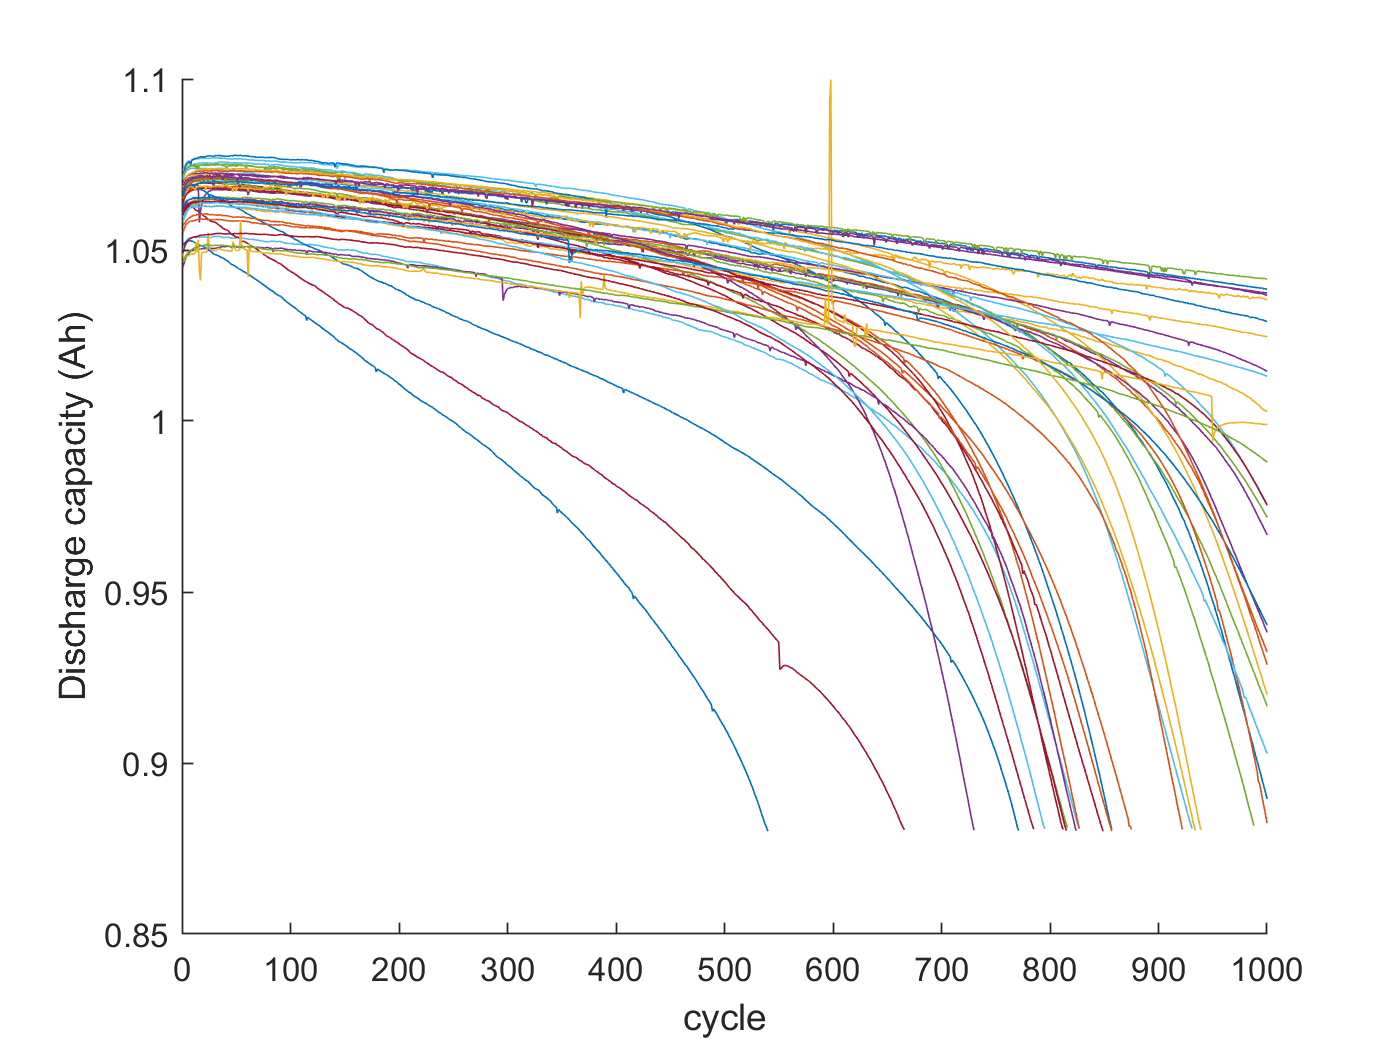

figure, hold on;
for i = 1:size(trainData,2)
    if numel(trainData(i).summary.cycle) == numel(unique(trainData(i).summary.cycle))
      plot(trainData(i).summary.cycle, trainData(i).summary.QDischarge);      
    end
end
ylim([0.85,1.1]),xlim([0,1000]);
ylabel('Discharge capacity (Ah)');
xlabel('cycle');

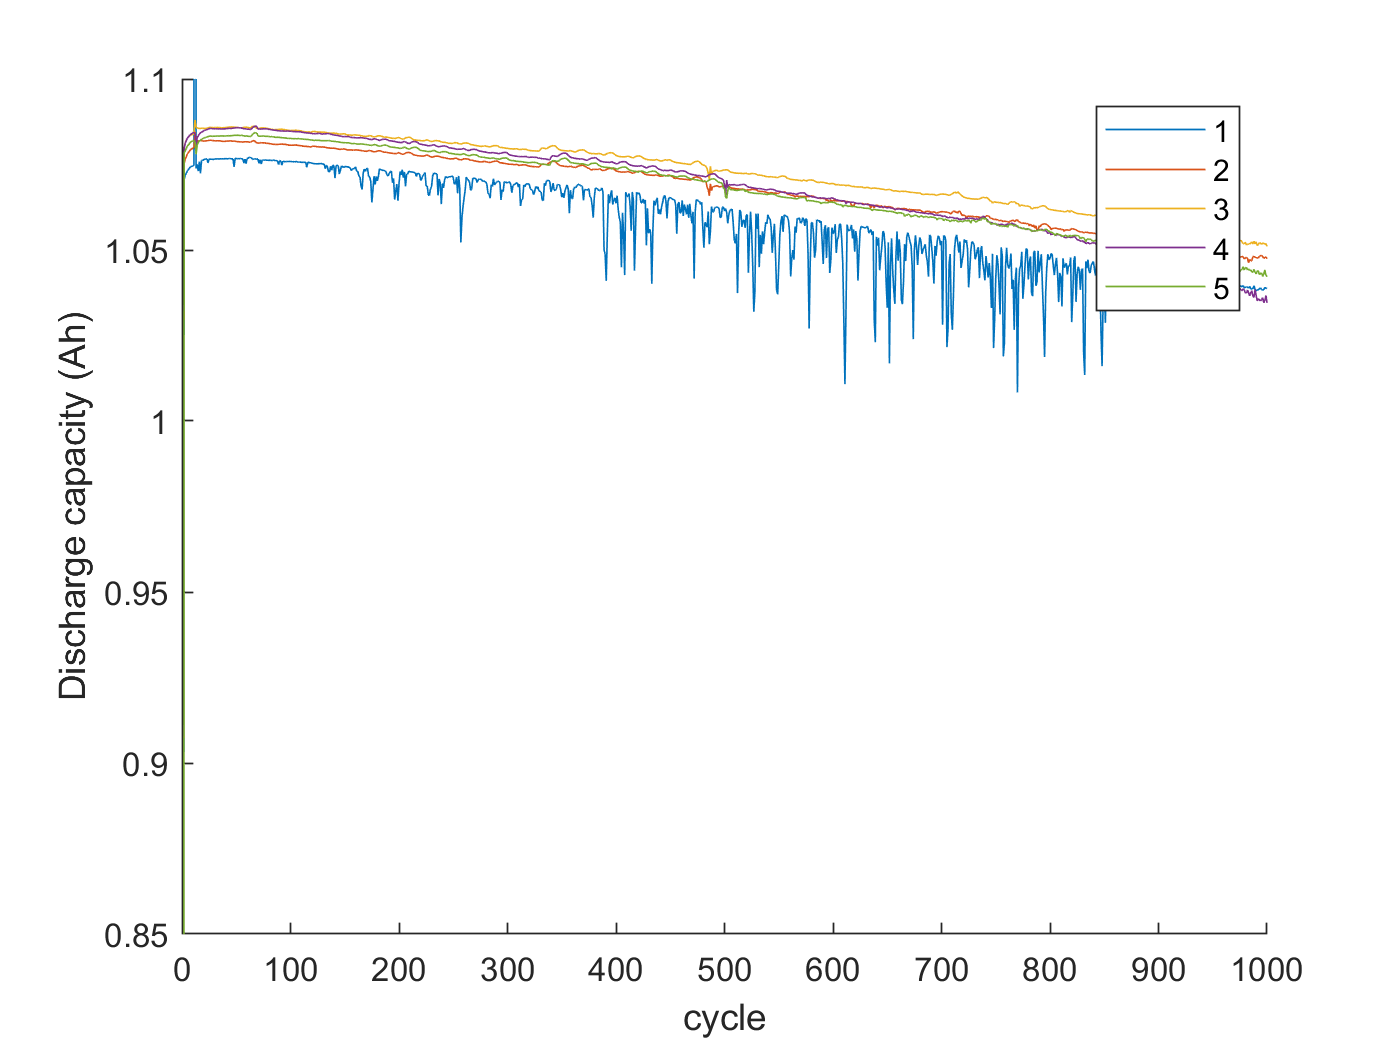

% https://kr.mathworks.com/matlabcentral/answers/3669-legend-dynamically-updated
figure, hold on;
b=zeros(5);
cycle_num =zeros(5);
j = 1;
for i = 1:5
    if numel(trainData(i).summary.cycle) == numel(unique(trainData(i).summary.cycle))
      b(j) = plot(trainData(i).summary.cycle, trainData(i).summary.QDischarge);  
      cycle_num(j) = i; % num2str(i);
      %legend(b(1:j))
      % https://kr.mathworks.com/help/matlab/matlab_prog/create-string-arrays.html
      legend(b(1:j),string(cycle_num(1:j)))
      j = j+1;
      %pause(1)
    end
end
ylim([0.85,1.1]),xlim([0,1000]);
ylabel('Discharge capacity (Ah)');
xlabel('cycle');

cycle poicy => 충전전류가 높은수록 더 안좋은 결과.

3  '4_4C-80PER_4_4C'	'4.4C(80%)-4.4C' 오래감

4  '4_8C-80PER_4_8C'	'4.8C(80%)-4.8C'  중간

5  '5_4C-50PER_3C'	'5.4C(50%)-3C'   짧음.

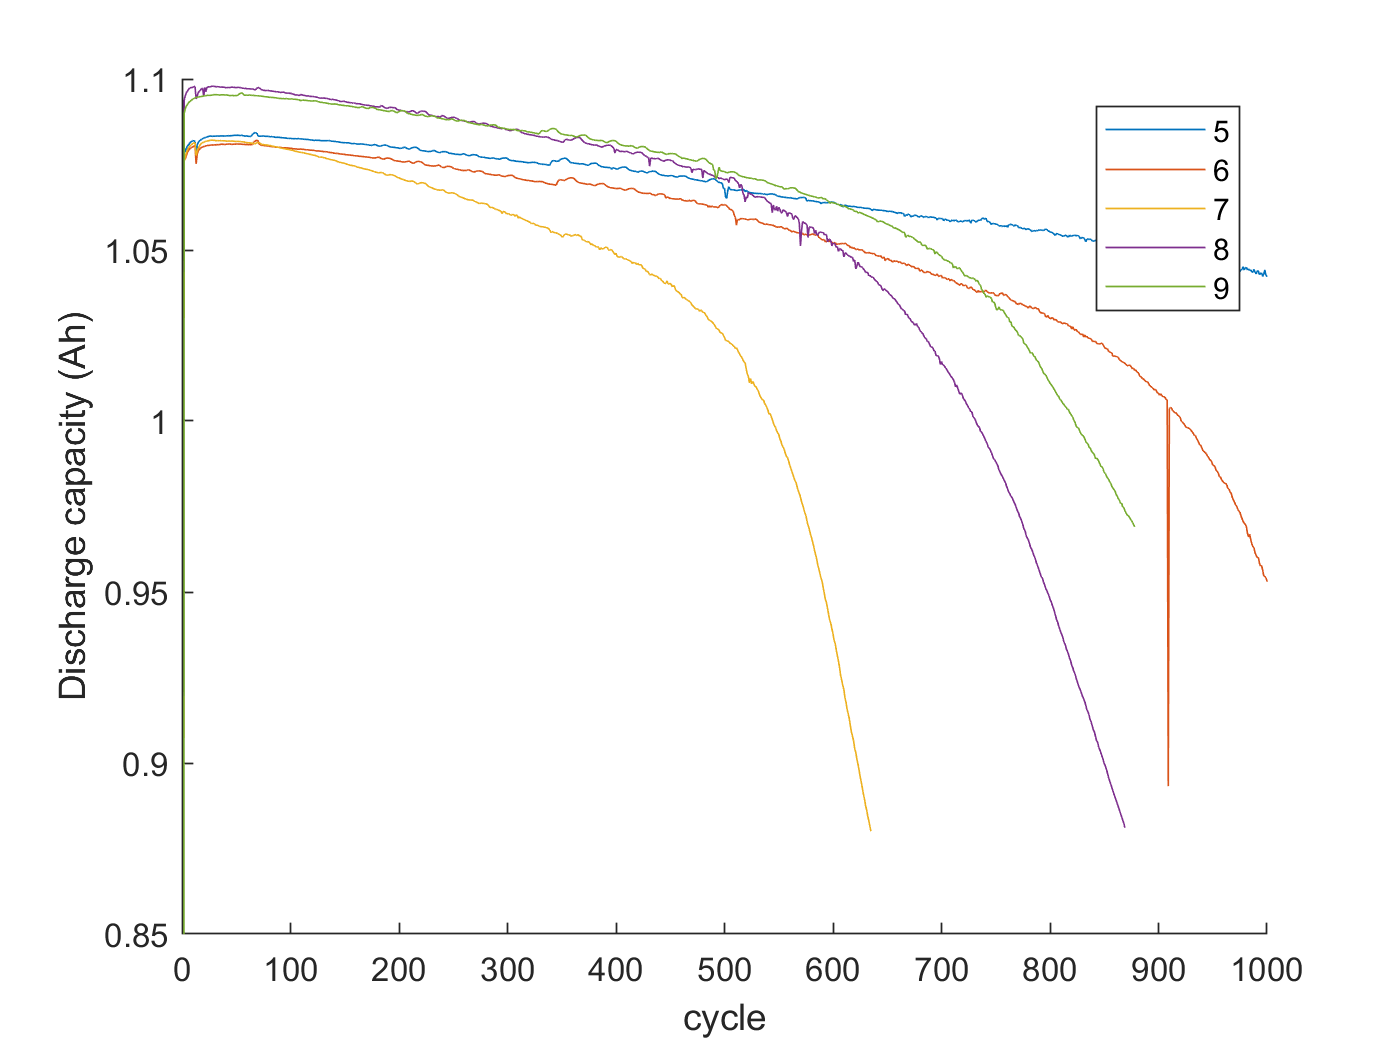


figure, hold on;
b=zeros(5);
cycle_num =zeros(5);
j = 1;
for i = 5:9
    if numel(trainData(i).summary.cycle) == numel(unique(trainData(i).summary.cycle))
      b(j) = plot(trainData(i).summary.cycle, trainData(i).summary.QDischarge);  
      cycle_num(j) = i; % num2str(i);
      %legend(b(1:j))
      % https://kr.mathworks.com/help/matlab/matlab_prog/create-string-arrays.html
      legend(b(1:j),string(cycle_num(1:j)))
      j = j+1;
      %pause(1)
    end
end
ylim([0.85,1.1]),xlim([0,1000]);
ylabel('Discharge capacity (Ah)');
xlabel('cycle');

5  '5_4C-50PER_3C'	'5.4C(50%)-3C'   짧음.

6  '5_4C-60PER_3C'	'5.4C(60%)-3C'	기준

7  '5_4C-60PER_3_6C'	'5.4C(60%)-3.6C'	6 보다 전반적으로 높은 C로 충전. 그런데 성능이 좋다. 이상 데이타.

8  '5_4C-70PER_3C'	'5.4C(70%)-3C'	6 보다 전반적으로 높은 C로 충전. 그런데 성능이 좋다. 이상 데이타.

9 '5_4C-80PER_5_4C'	'5.4C(80%)-5.4C'	"EL150800463871"	"12"	559	1x558 struct	1x1 struct	1000x1 double

10 '6C-40PER_3C'	'6C(40%)-3C'	"EL150800460630"	"25"	1017	1x1016 struct	1x1 struct	1000x1 double

/////////////

1 '3_6C-80PER_3_6C'	'3.6C(80%)-3.6C'	"EL150800460486"	"2"	1179	1x2159 struct	1x1 struct	1000x1 double

2 '4C-80PER_4C'	'4C(80%)-4C'	"EL150800464977"	"5"	1226	1x1433 struct	1x1 struct	1000x1 double

3  '4_4C-80PER_4_4C'	'4.4C(80%)-4.4C'	"EL150800464883"	"7"	1074	1x1073 struct	1x1 struct	1000x1 double

4  '4_8C-80PER_4_8C'	'4.8C(80%)-4.8C'	"EL150800465027"	"9"	870	1x869 struct	1x1 struct	1000x1 double

5  '5_4C-50PER_3C'	'5.4C(50%)-3C'	"EL150800463882"	"14"	788	1x787 struct	1x1 struct	1000x1 double

6  '5_4C-60PER_3C'	'5.4C(60%)-3C'	"EL150800453113"	"16"	719	1x718 struct	1x1 struct	1000x1 double

7  '5_4C-60PER_3_6C'	'5.4C(60%)-3.6C'	"EL150800460522"	"24"	857	1x856 struct	1x1 struct	1000x1 double

8  '5_4C-70PER_3C'	'5.4C(70%)-3C'	"EL150800464881"	"18"	788	1x787 struct	1x1 struct	1000x1 double

9 '5_4C-80PER_5_4C'	'5.4C(80%)-5.4C'	"EL150800463871"	"12"	559	1x558 struct	1x1 struct	1000x1 double

10 '6C-40PER_3C'	'6C(40%)-3C'	"EL150800460630"	"25"	1017	1x1016 struct	1x1 struct	1000x1 double

'6C-40PER_3_6C'	'6C(40%)-3.6C'	"EL150800460659"	"33"	870	1x869 struct	1x1 struct	1000x1 double

'6C-50PER_3C'	'6C(50%)-3C'	"EL150800460507"	"27"	860	1x859 struct	1x1 struct	1000x1 double

'6C-50PER_3_6C'	'6C(50%)-3.6C'	"EL150800460615"	"35"	709	1x708 struct	1x1 struct	1000x1 double

'6C-60PER_3C'	'6C(60%)-3C'	"EL150800460640"	"29"	731	1x730 struct	1x1 struct	1000x1 double

'7C-30PER_3_6C'	'7C(30%)-3.6C'	"EL150800460525"	"39"	742	1x741 struct	1x1 struct	1000x1 double

'7C-40PER_3C'	'7C(40%)-3C'	"EL150800460506"	"37"	704	1x703 struct	1x1 struct	1000x1 double

'7C-40PER_3_6C'	'7C(40%)-3.6C'	"EL150800453773"	"41"	617	1x616 struct	1x1 struct	1000x1 double

'8C-15PER_3_6C'	'8C(15%)-3.6C'	"EL150800463229"	"43"	966	1x965 struct	1x1 struct	1000x1 double

'8C-25PER_3_6C'	'8C(25%)-3.6C'	"EL150800460618"	"45"	702	1x701 struct	1x1 struct	1000x1 double

'8C-35PER_3_6C'	'8C(35%)-3.6C'	"EL150800460485"	"47"	616	1x615 struct	1x1 struct	1000x1 double

[https://www.power-sonic.com/blog/what-is-a-battery-c-rating/](https://www.power-sonic.com/blog/what-is-a-battery-c-rating/)

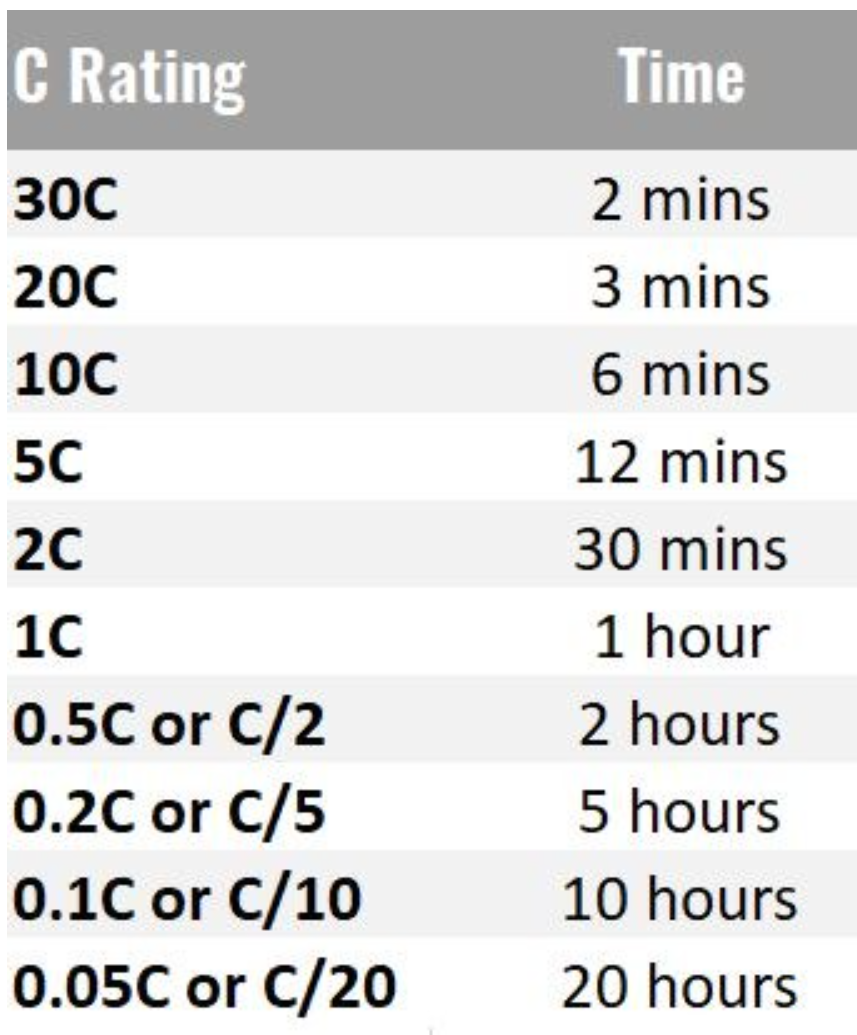

C:\nobackup\_phd_work\_battery_soh\__doc_battery\346501527888d799d94279cfe74049fde53ca2d5a1275d083d28f925253cf657.pdf

이 데이타는 charging protocol 에 관련된 사항이며 discharge 는 모두 동일한 조건에서 수행한다.

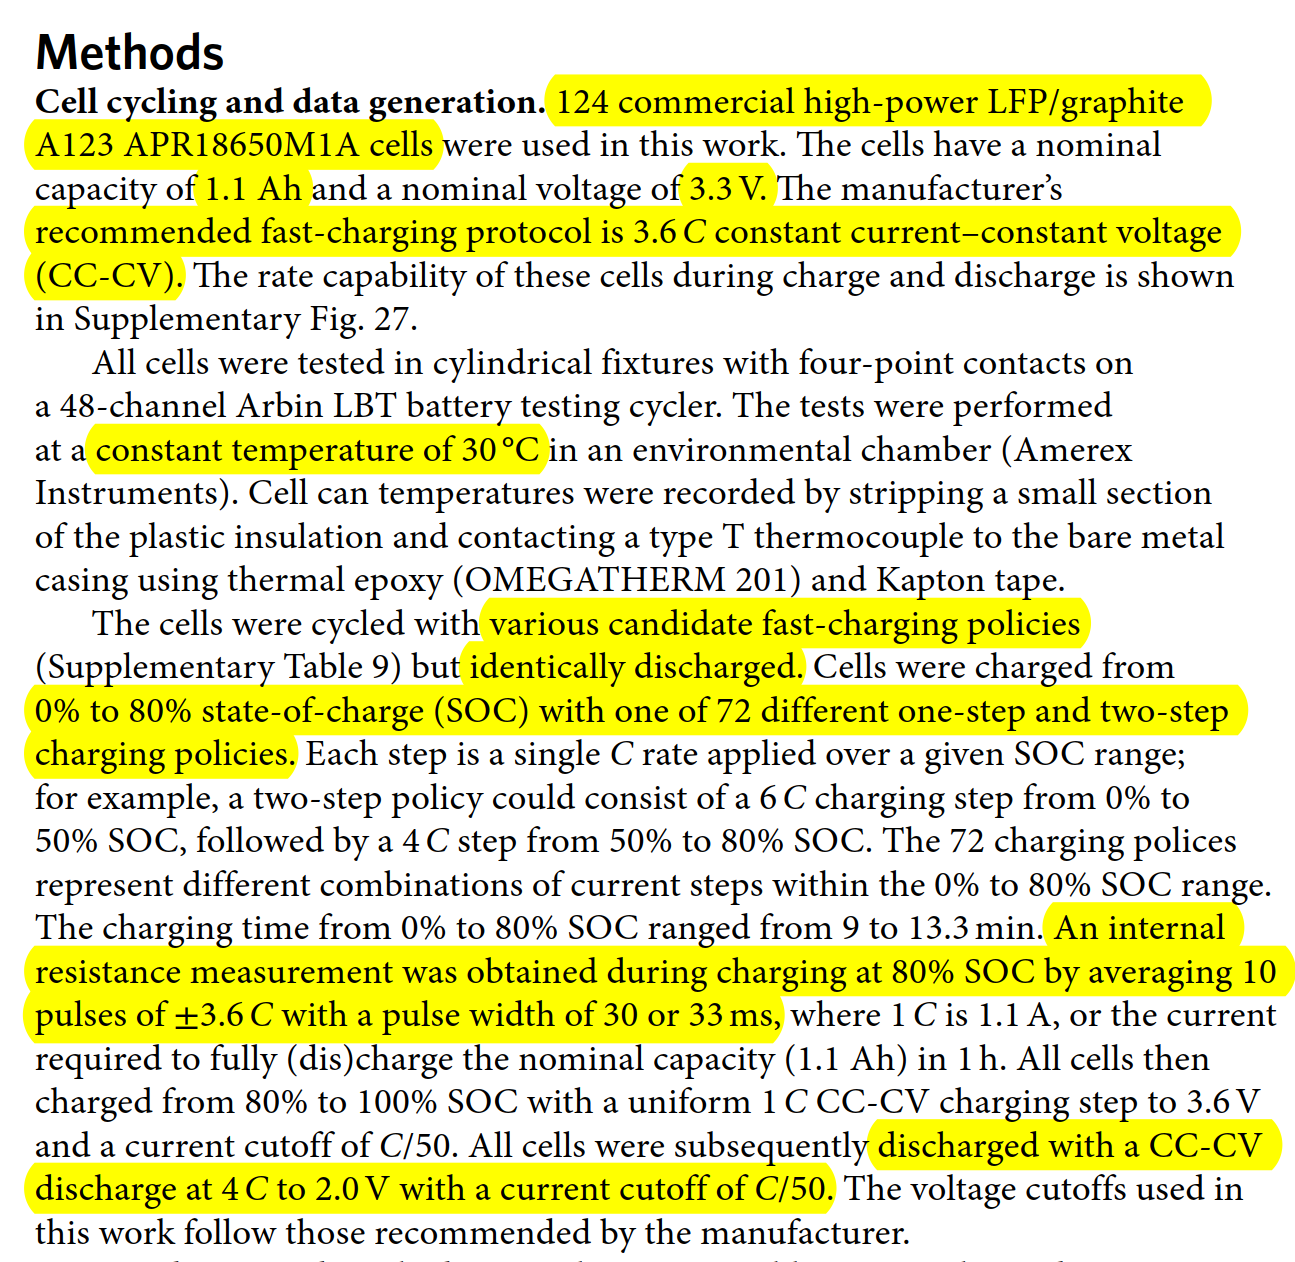

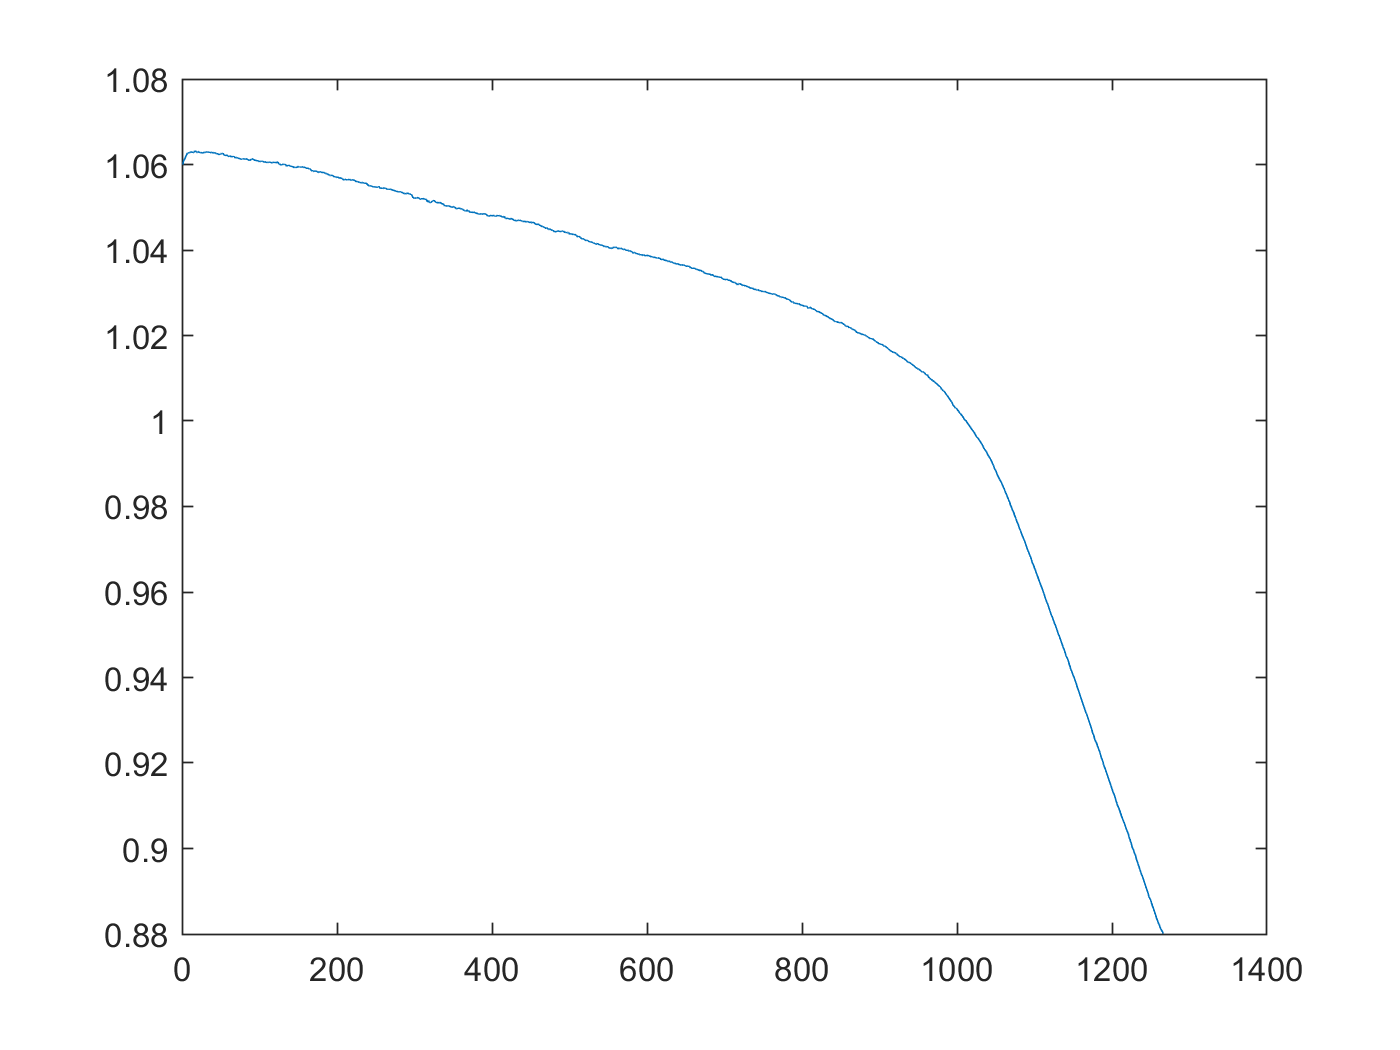

figure
plot(trainData(3).summary.cycle, trainData(3).summary.QDischarge)

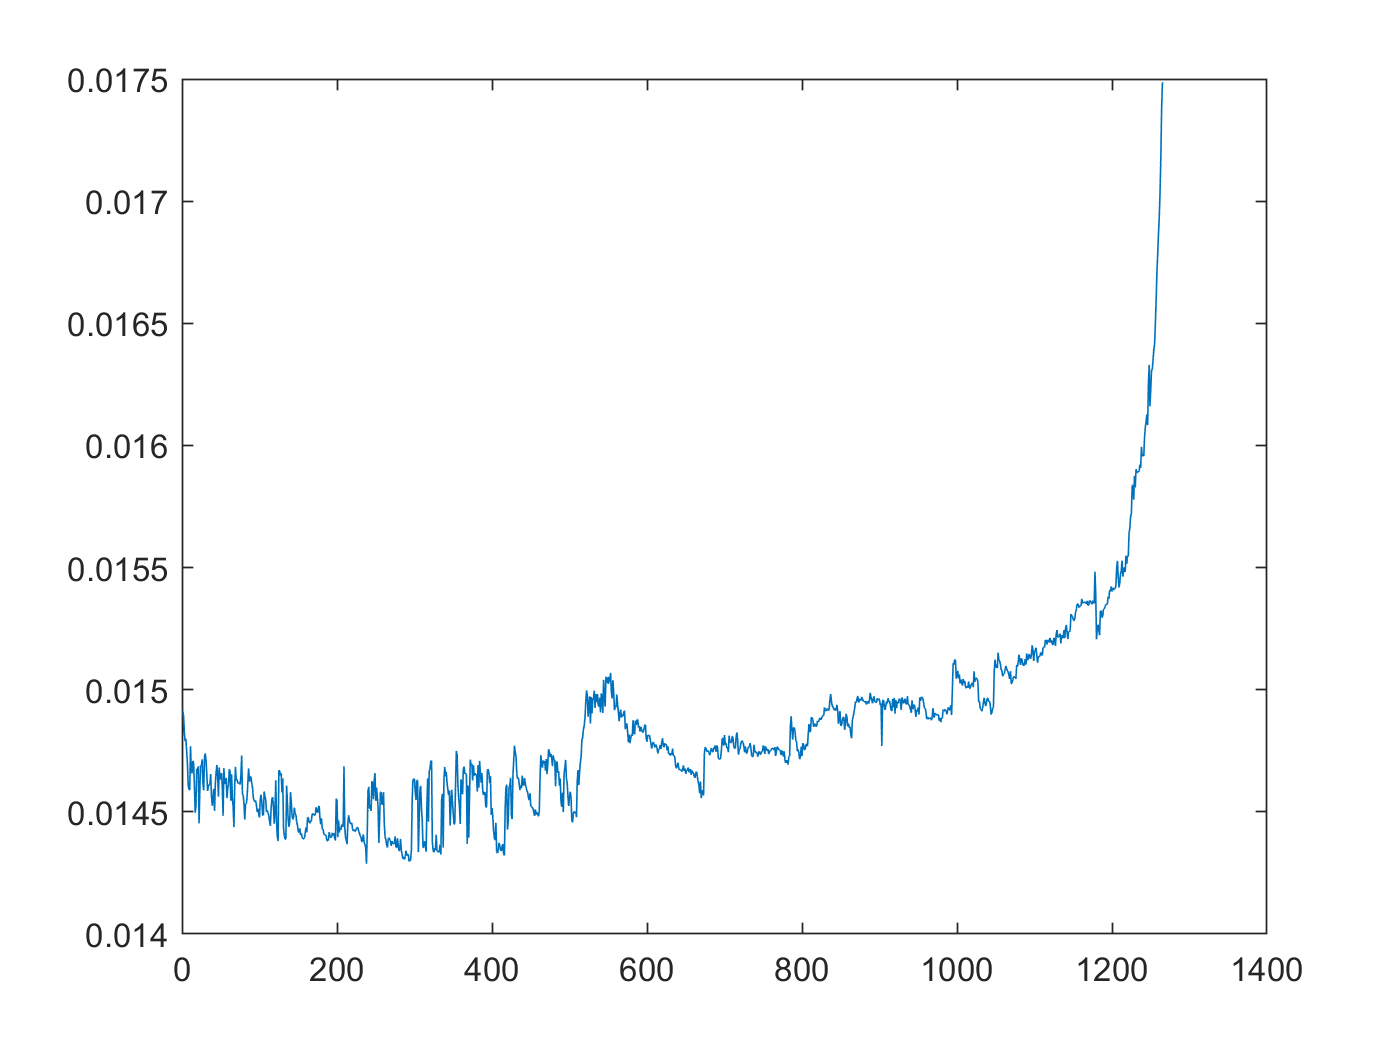

figure
plot(trainData(3).summary.cycle,trainData(3).summary.IR)

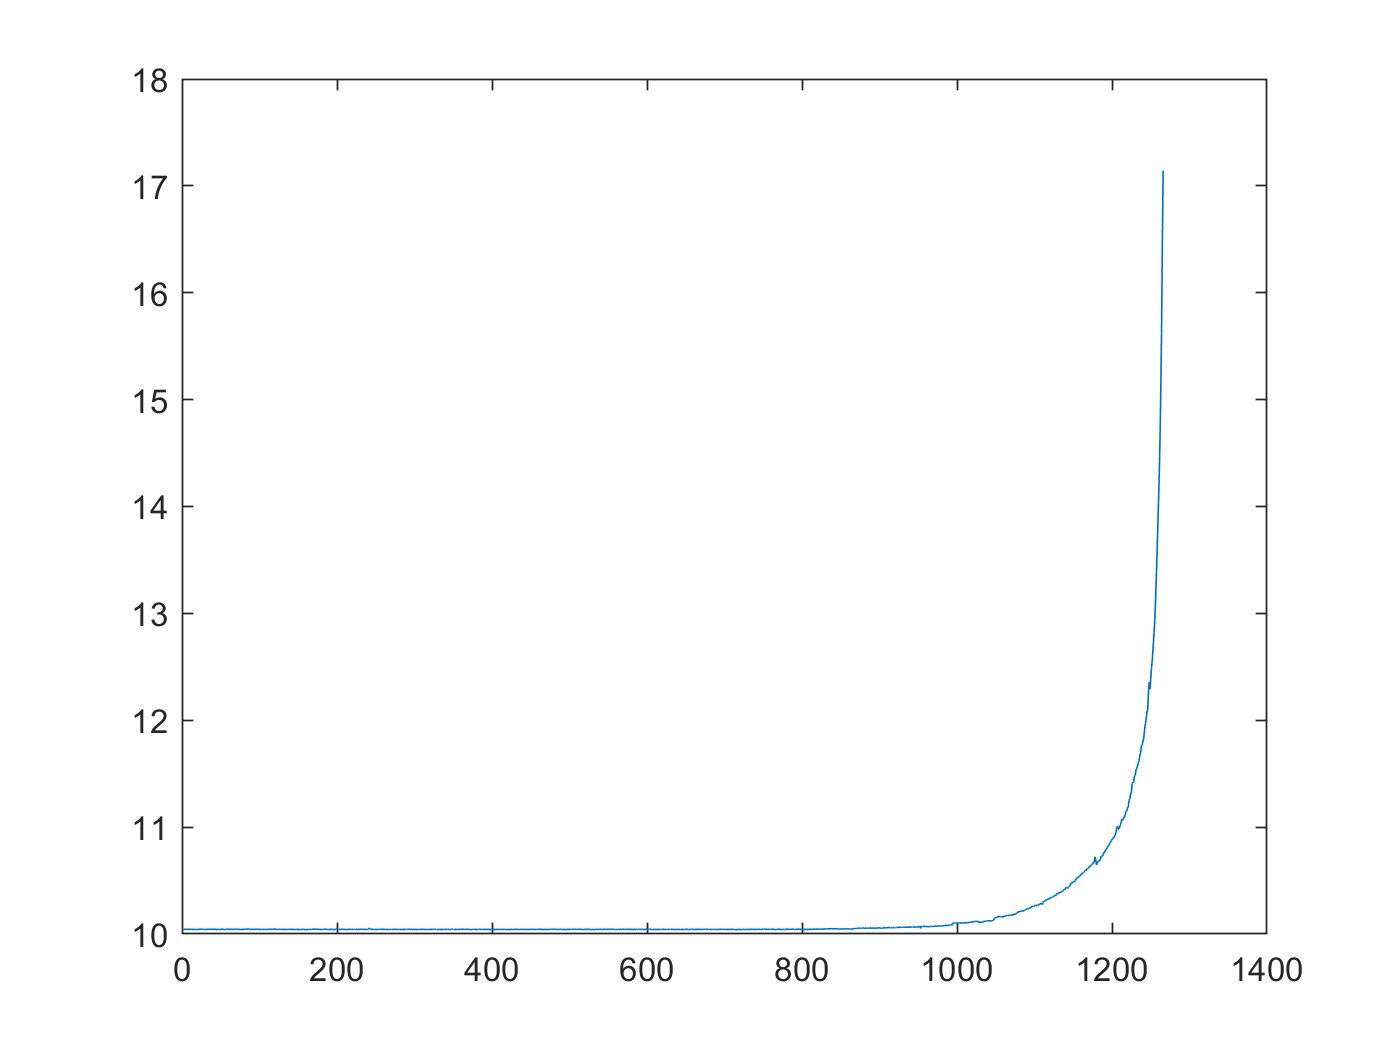


figure
plot(trainData(3).summary.cycle,trainData(3).summary.chargetime)

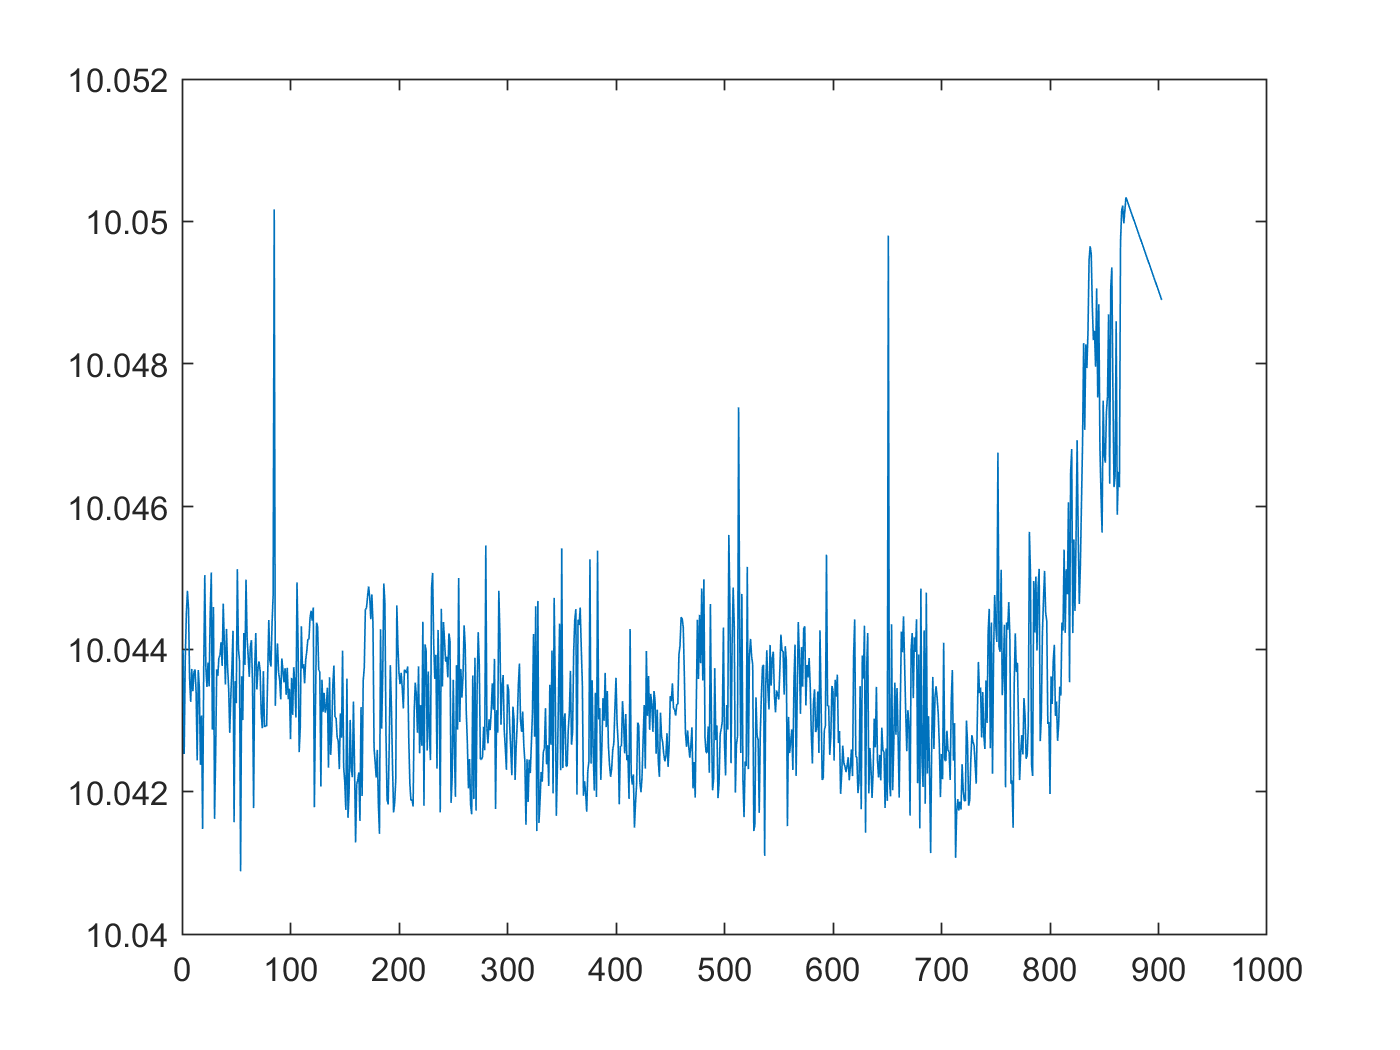

% https://kr.mathworks.com/help/matlab/ref/rmoutliers.html
[chargetime_new,TF] = rmoutliers(trainData(3).summary.chargetime);
figure
plot(trainData(3).summary.cycle(~TF),chargetime_new)

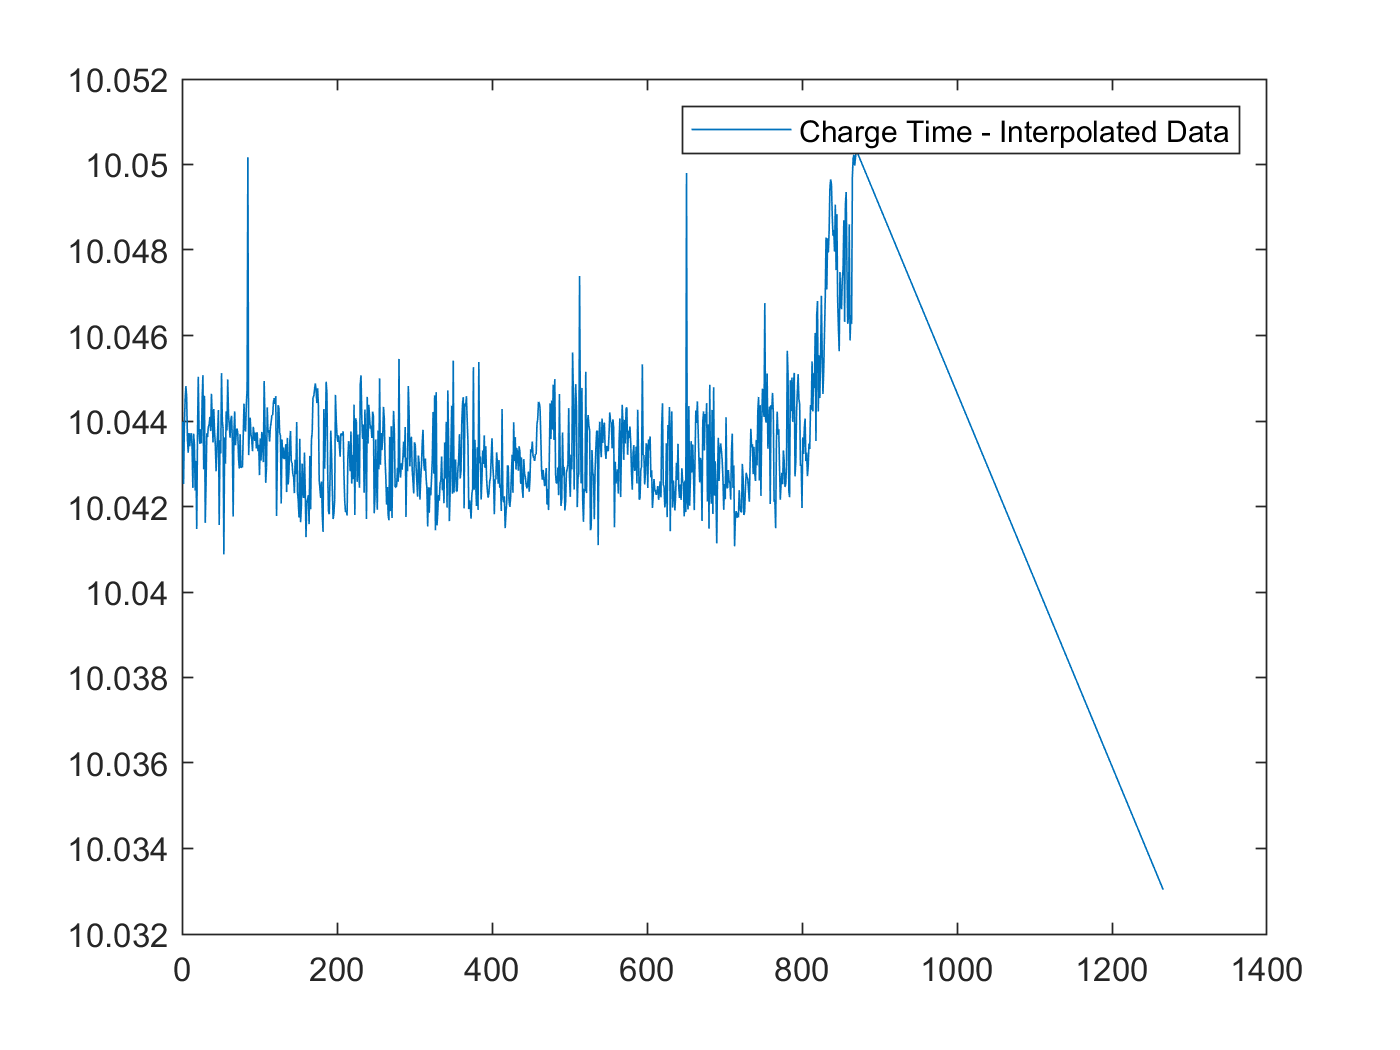

% https://kr.mathworks.com/help/matlab/ref/filloutliers.html

chargetime_interpolation = filloutliers(trainData(3).summary.chargetime,'linear');
plot(trainData(3).summary.cycle,chargetime_interpolation)
legend('Charge Time - Interpolated Data')

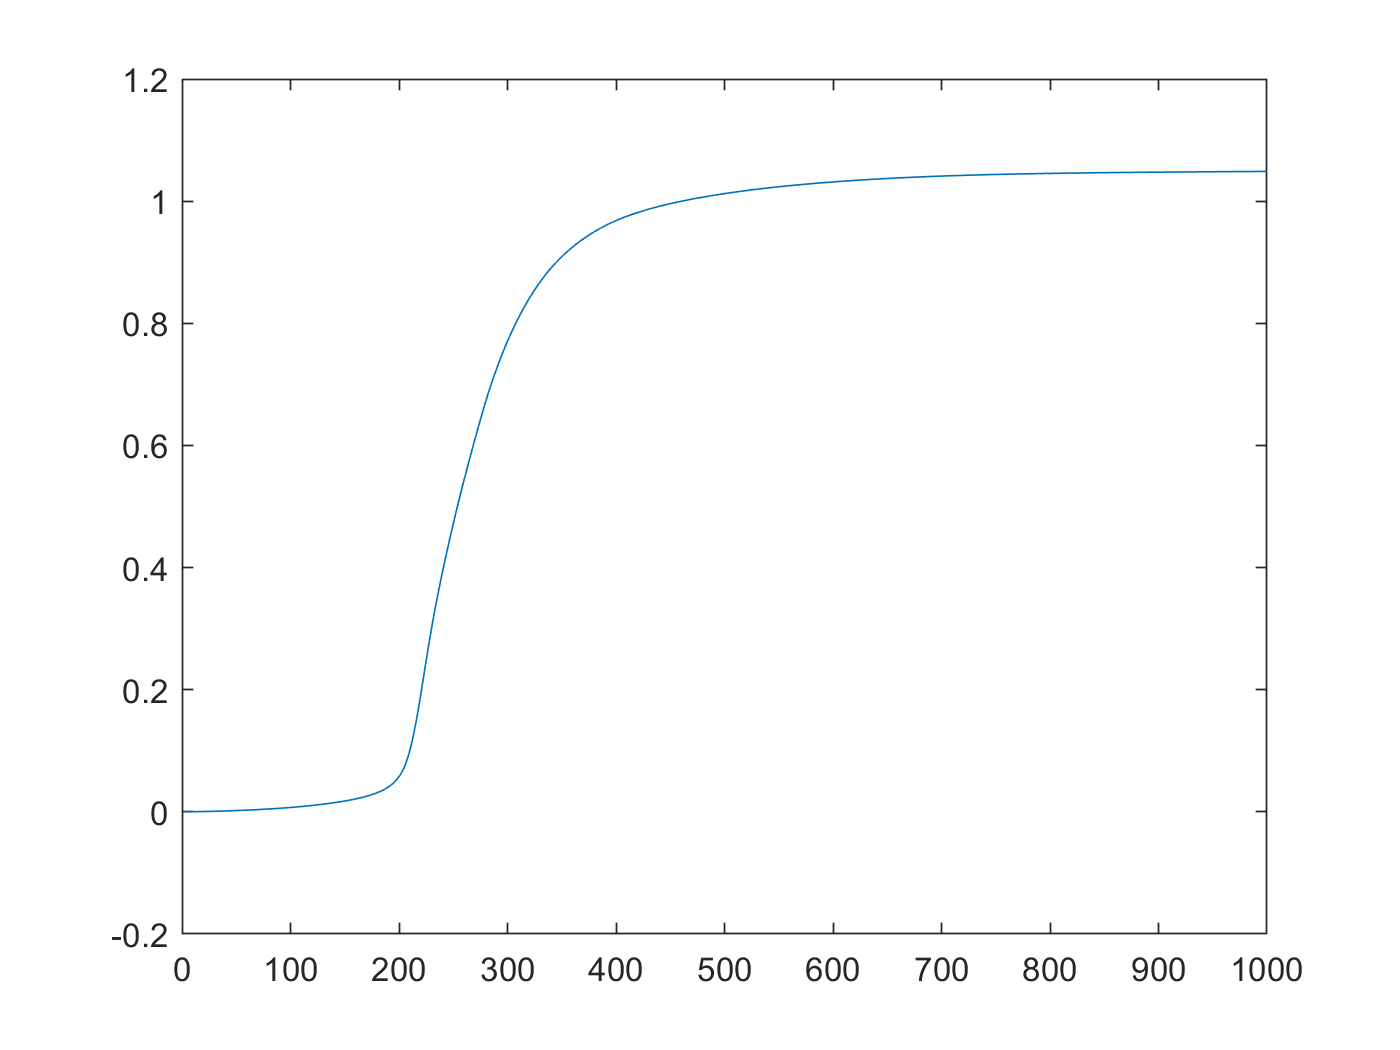


%
figure
plot(trainData(3).cycles(10).Qdlin)

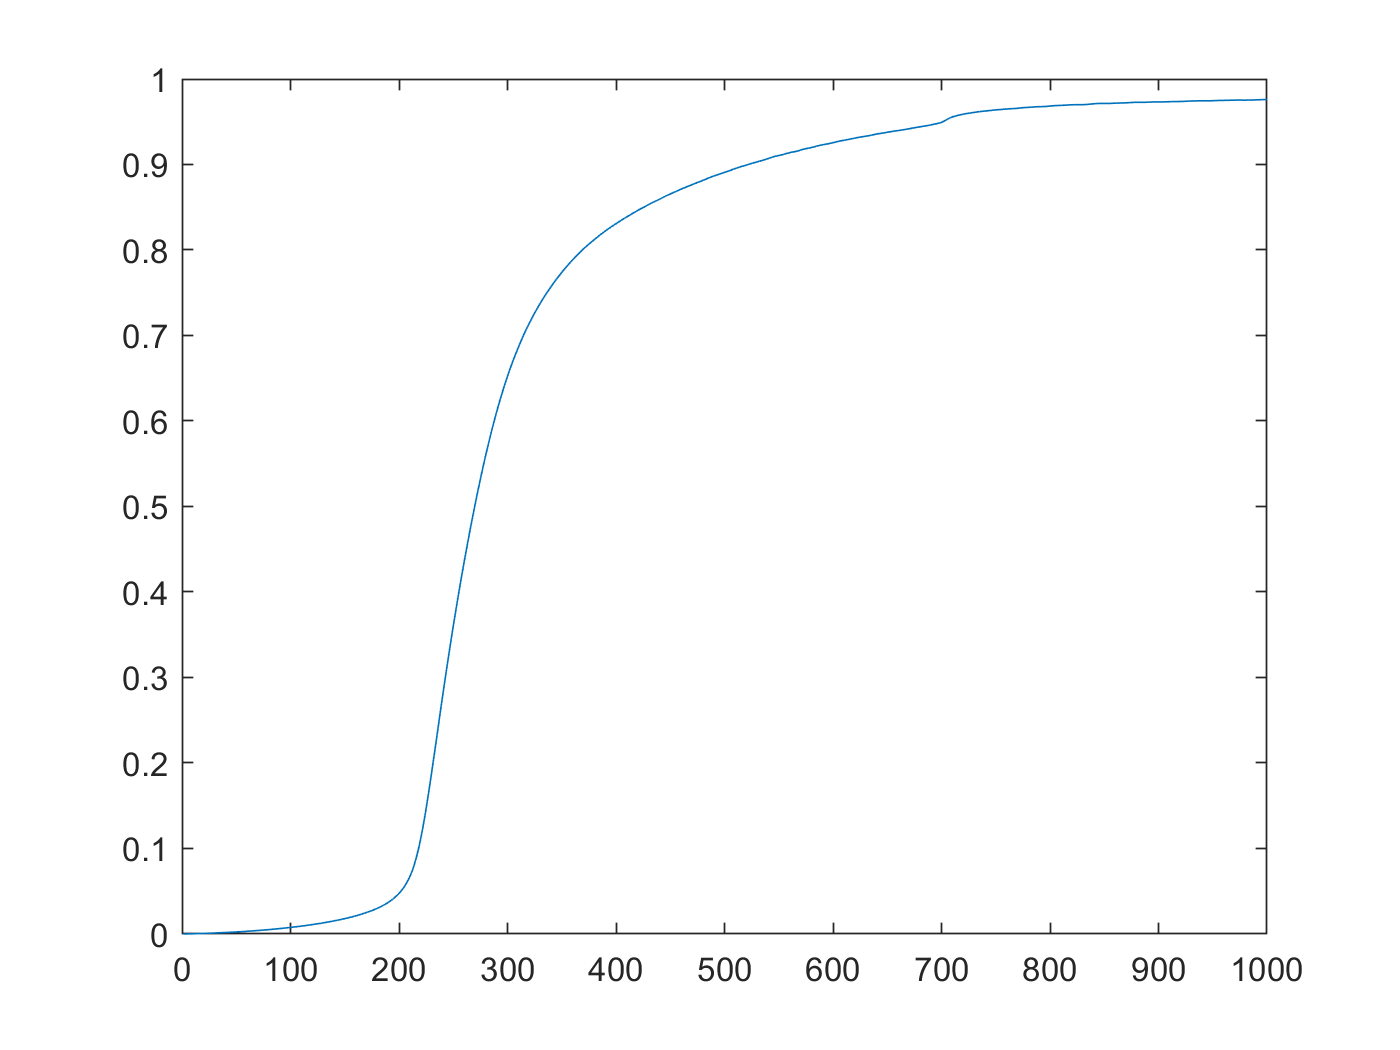

plot(trainData(3).cycles(1000).Qdlin)

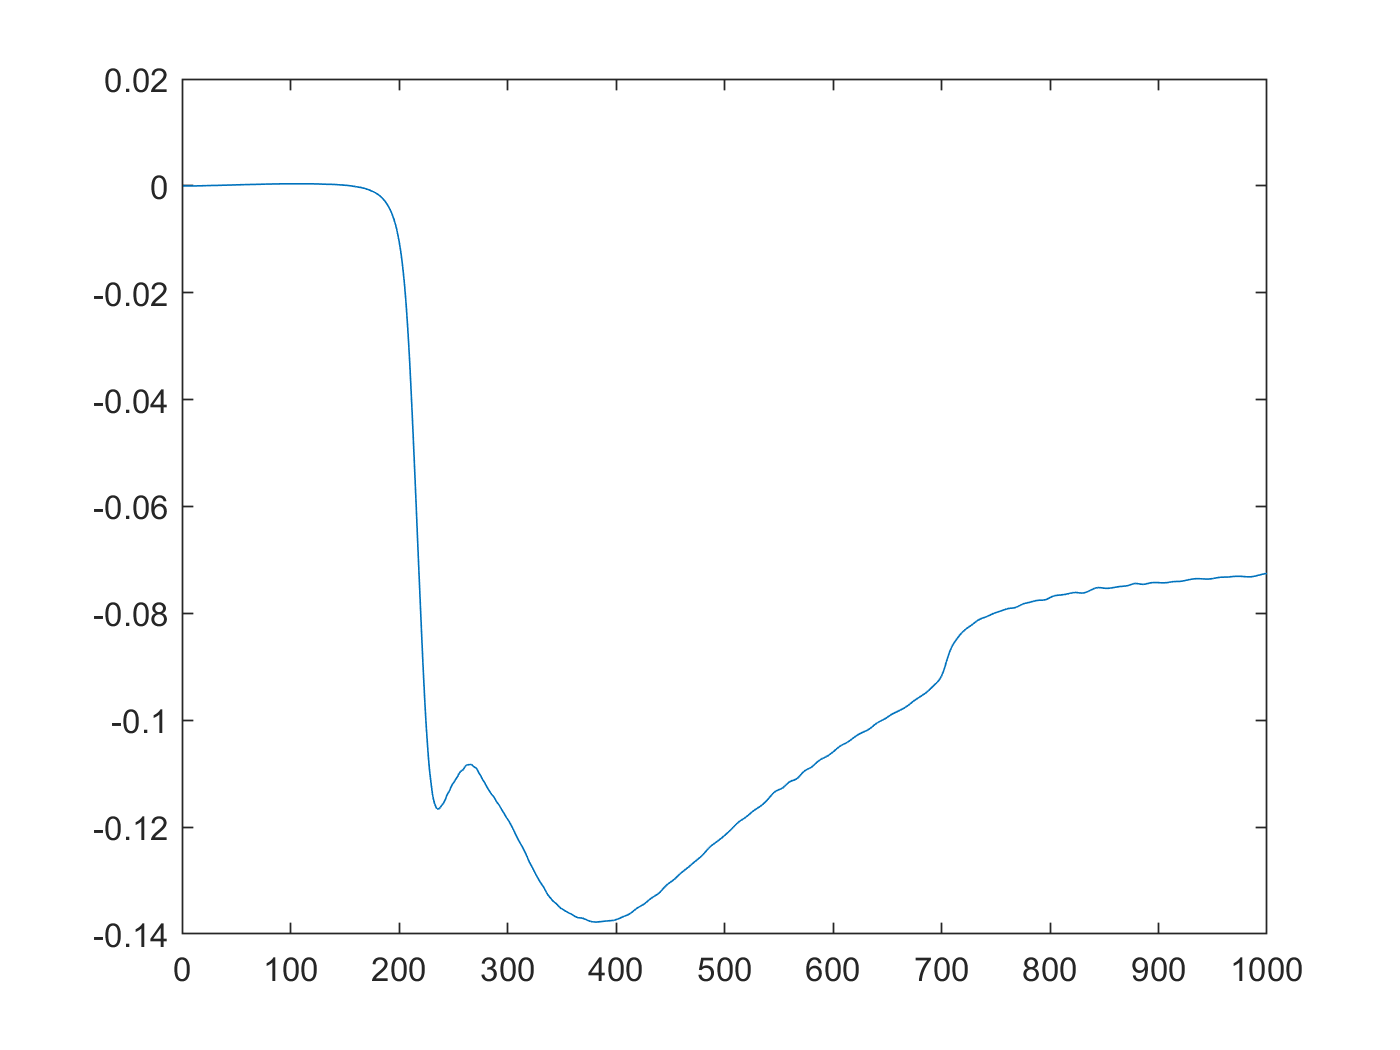

plot(trainData(3).cycles(1000).Qdlin - trainData(3).cycles(10).Qdlin  )

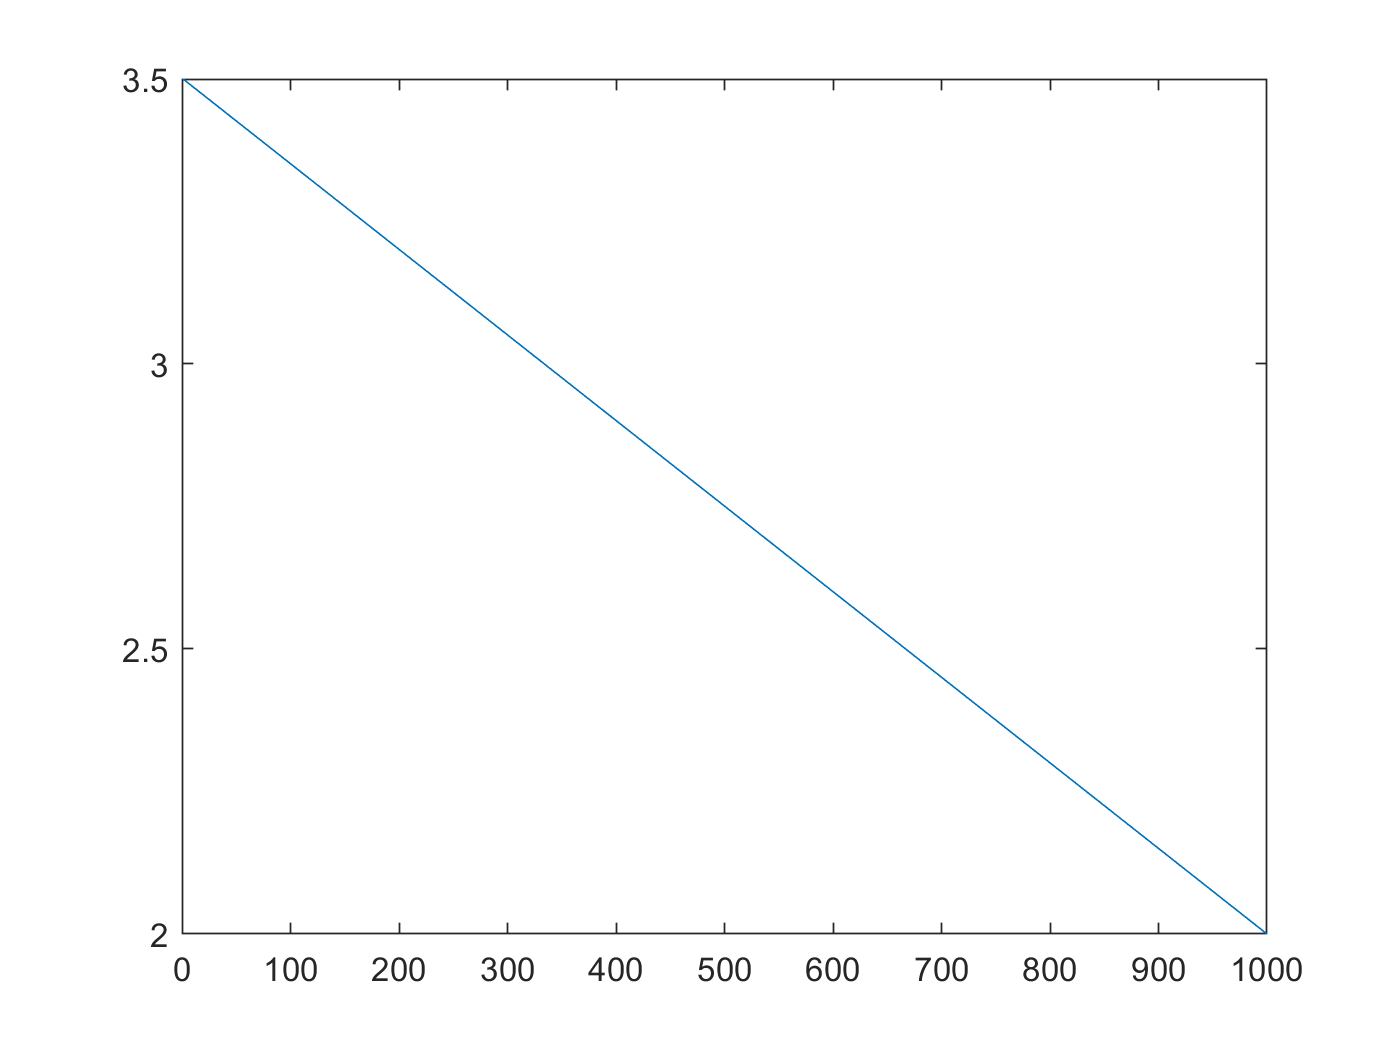

plot(trainData(3).Vdlin )

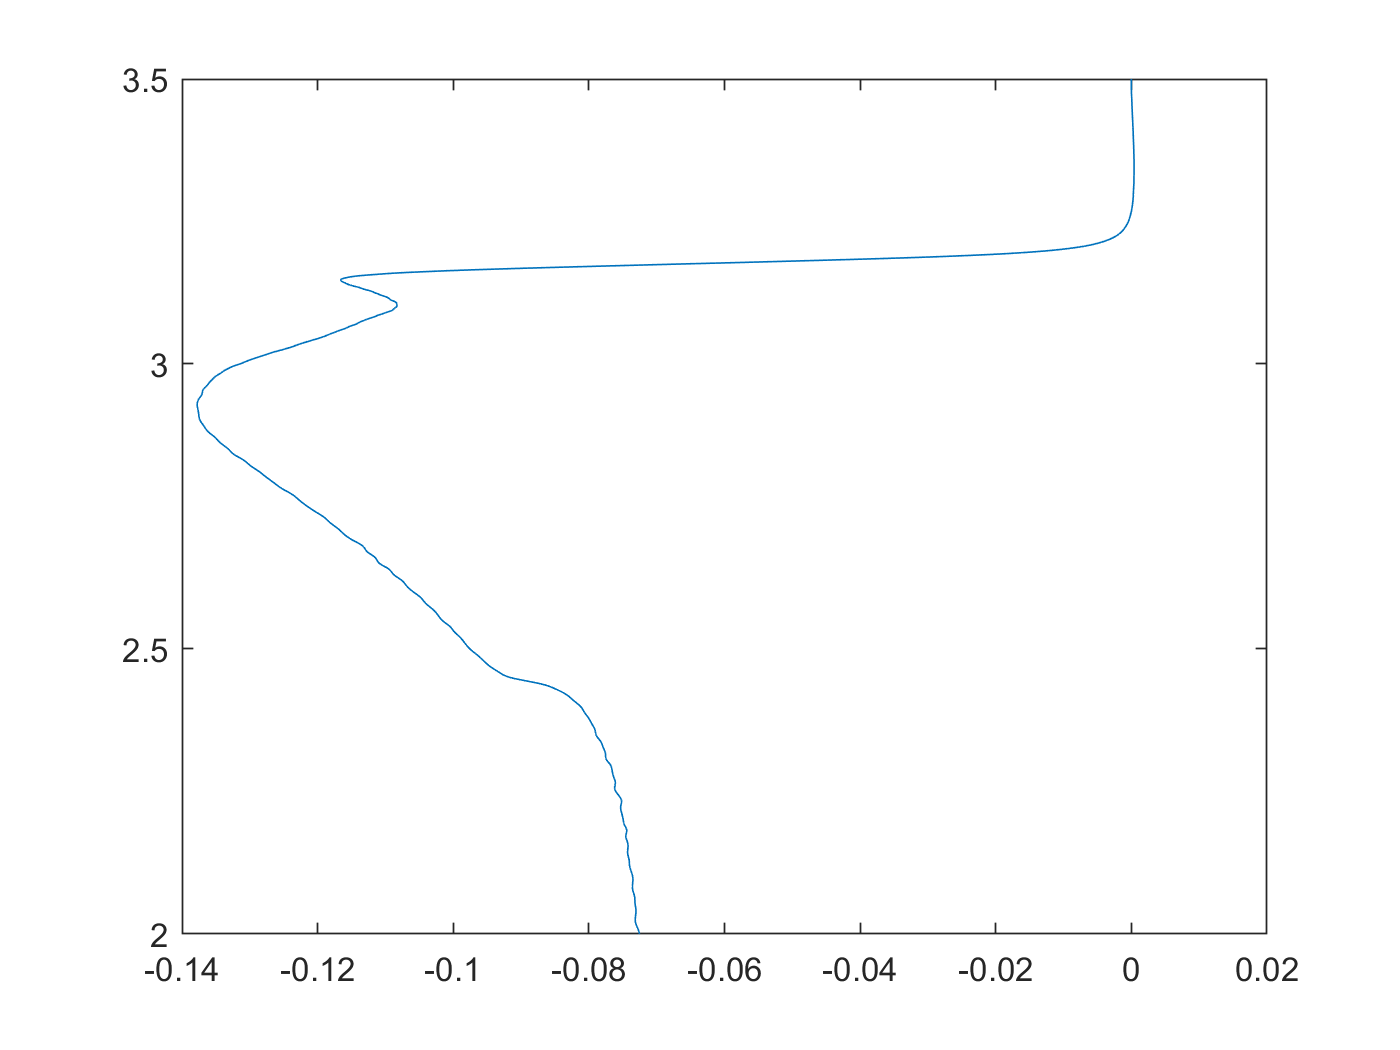

plot((trainData(3).cycles(1000).Qdlin - trainData(3).cycles(10).Qdlin), trainData(3).Vdlin )

As seen in the plot, capacity fade accelerates near the end of life. However, **capacity fade is negligible in the first 100 cycles and by itself is not a good feature for battery cycle life prediction**. Therefore, a data-driven approach that considers **voltage curves of each cycle**, along with additional measurements, including **cell internal resistance and temperature**, is considered for predicting remaining cycle life. The cycle-to-cycle evolution of Q(V), the discharge voltage curve as a function of voltage for a given cycle, is an important feature space [1]. In particular, the change in discharge voltage curves between cycles, $$\Delta Q(V)$$, is very effective in degradation diagnosis. Therefore, select the difference in discharge capacity as a function of voltage between 100th and 10th cycle, $\Delta Q_{100-10}(V)$. 

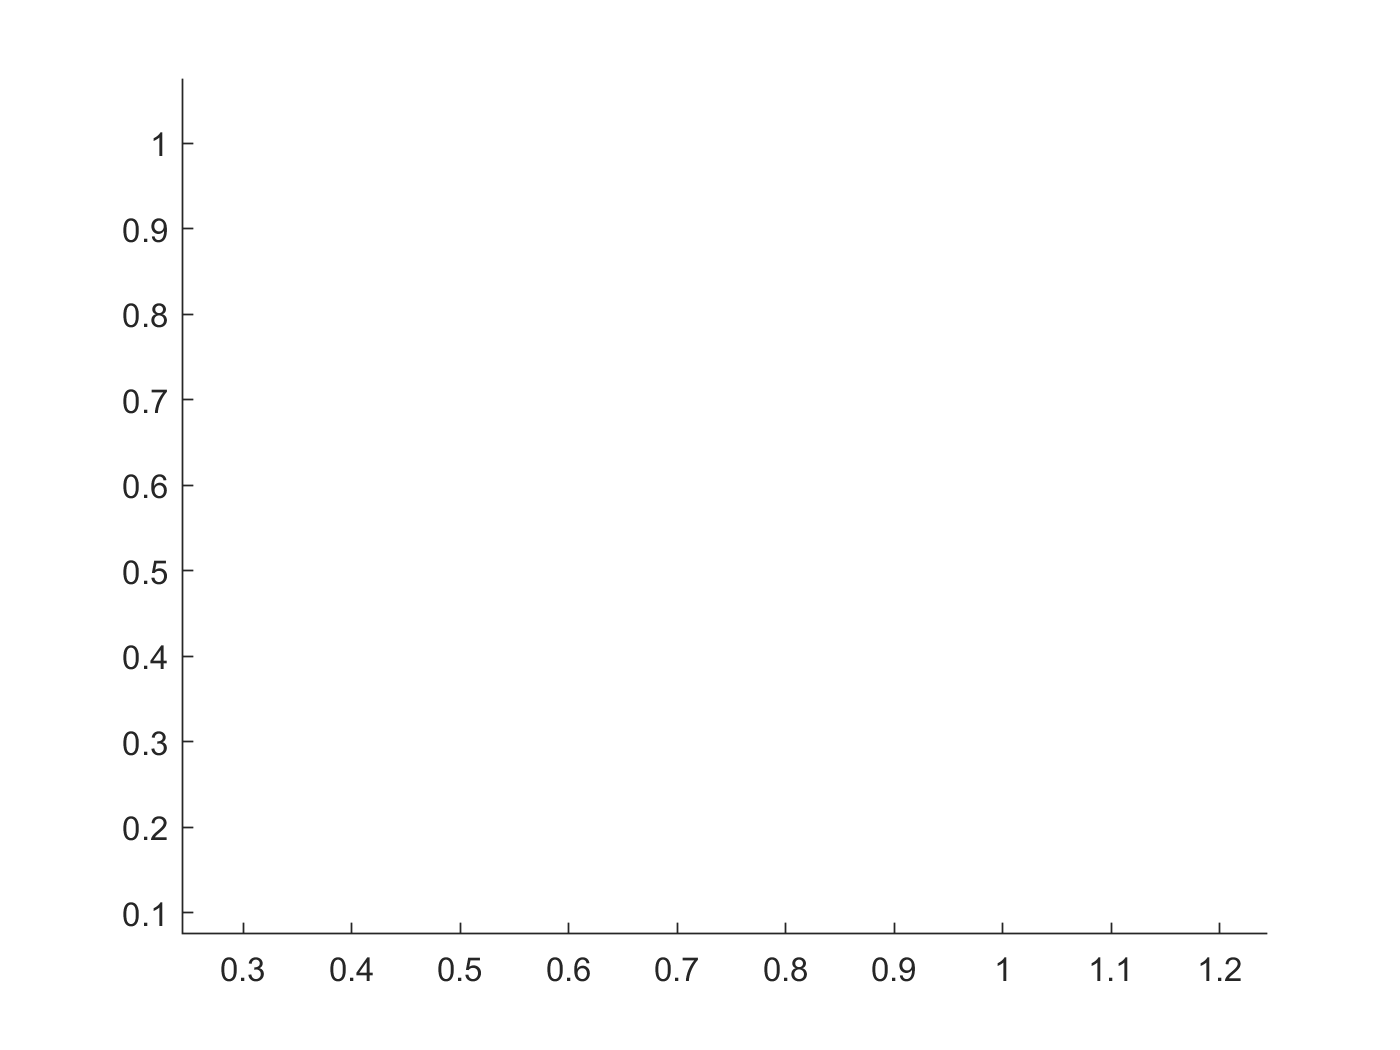

figure, hold on;
for i = 1:size(testData,2)
    plot((testData(i).cycles(100).Qdlin - testData(i).cycles(10).Qdlin), testData(i).Vdlin)   
end

ylabel('Voltage (V)'); xlabel('Q_{100} - Q_{10} (Ah)');

Unrecognized function or variable 'testData'.

Compute summary statistics using $\Delta Q_{100-10}(V)$ curves of each cell as the condition indicator. It is important to bear in mind that these summary statistics do not need to have a clear physical meaning, they just need to exhibit predictive capabilities. For example, the variance of $\Delta Q_{100-10}(V)$ and cycle life are highly correlated as seen in this log–log plot, thereby confirming this approach.

figure;
trainDataSize = size(trainData,2);
cycleLife = zeros(trainDataSize,1);
DeltaQ_var = zeros(trainDataSize,1);
for i = 1:trainDataSize
    cycleLife(i) = size(trainData(i).cycles,2) + 1;
    DeltaQ_var(i) = var(trainData(i).cycles(100).Qdlin - trainData(i).cycles(10).Qdlin);
end
loglog(DeltaQ_var,cycleLife, 'o')
ylabel('Cycle life'); xlabel('Var(Q_{100} - Q_{10}) (Ah^2)');

Next, extract the following features from the raw measurement data (the variable names are in brackets) [1]:

- $\Delta Q_{100-10}(V)$ log variance [DeltaQ_var]

- $\Delta Q_{100-10}(V)$ log minimum [DeltaQ_min]

- Slope of linear fit to capacity fade curve, cycles 2 to 100 [CapFadeCycle2Slope]

- Intercept of linear fit to capacity fade curve, cycles 2 to 100 [CapFadeCycle2Intercept]

- Discharge capacity at cycle 2 [Qd2]

- Average charge time over first 5 cycles [AvgChargeTime]

- Minimum Internal Resistance, cycles 2 to 100 [MinIR]

- Internal Resistance difference between cycles 2 and 100 [IRDiff2And100]

The `helperGetFeatures` function accepts the raw measurement data and computes the above listed features. It returns `XTrain` containing the features in a table and `yTrain` containing the expected remaining cycle life.

[XTrain,yTrain] = helperGetFeatures(trainData);
head(XTrain)

### Model Development: Linear Regression with Elastic Net Regularization

Use a regularized linear model to predict the remaining cycle life of a cell. Linear models have low computational cost but provide high interpretability. The linear model is of the form:


$$y_i = \mathbf{w}^T\mathbf{x}_i + \beta$$


where $y_i$ is the number of cycles for cell $i$, $\mathbf{x}_i$ is a $p$-dimensional feature vector for cell $i$ and $\mathbf{w}$ is $p$-dimensional model coefficient vector and $\beta$ is a scalar intercept. **The linear model is regularized using elastic net to address high correlations between the features**. For $\alpha$ strictly between 0 and 1, and nonnegative $\lambda$, the regularization coefficient, elastic net solves the problem:


$$\hat{\mathbf{w}} = {\min}_w \Vert \mathbf{y}-\mathbf{Xw} - \beta\Vert^2_2 + \lambda P_\alpha(\mathbf{w})$$


where $P_\alpha(\mathbf{w})= \frac{(1-\alpha)}{2} \Vert\mathbf{w}\Vert_2^2 + \alpha \Vert\mathbf{w}\Vert_1$. Elastic net approaches ridge regression when $\alpha$ is close to 0 and it is the same as lasso regularization when $\alpha=1$. Training data is used to choose the hyperparameters $\alpha$ and $\lambda$, and determine values of the coefficients, $\mathbf{w}$. The `lasso` function returns fitted least-squares regression coefficients and information about the fit of the model as output for each $\alpha$ and $\lambda$ value. The `lasso `function accepts a vector of values for $\lambda$ parameter. Therefore, for each value of $\alpha$, the model coefficients $\mathbf{w}$ and $\lambda$ yielding the lowest RMSE value is computed. As proposed in [1], use four-fold cross validation with 1 Monte Carlo repetition for cross-validation. 

rng("default")

alphaVec = 0.01:0.1:1;
lambdaVec = 0:0.01:1;
MCReps = 1;
cvFold = 4;

rmseList = zeros(length(alphaVec),1);
minLambdaMSE = zeros(length(alphaVec),1);
wModelList = cell(1,length(alphaVec));
betaVec = cell(1,length(alphaVec));

for i=1:length(alphaVec)
    [coefficients,fitInfo] = ...
        lasso(XTrain.Variables,yTrain,'Alpha',alphaVec(i),'CV',cvFold,'MCReps',MCReps,'Lambda',lambdaVec);
    wModelList{i} = coefficients(:,fitInfo.IndexMinMSE);
    betaVec{i} = fitInfo.Intercept(fitInfo.IndexMinMSE);       
    indexMinMSE = fitInfo.IndexMinMSE;
    rmseList(i) = sqrt(fitInfo.MSE(indexMinMSE));    
    minLambdaMSE(i) = fitInfo.LambdaMinMSE;    
end

To make the fitted model robust, use validation data to select final values of $\alpha$ and $\lambda$ hyperparameters. To this end, pick the coefficients corresponding to the four lowest RMSE values computed using the training data.

numVal = 4;
[out,idx] = sort(rmseList);
val = out(1:numVal);
index = idx(1:numVal);

alpha = alphaVec(index);
lambda = minLambdaMSE(index);
wModel = wModelList(index);
beta = betaVec(index);

For each set of coefficients, compute the predicted values and RMSE on validation data. 

[XVal,yVal] = helperGetFeatures(valData);
rmseValModel = zeros(numVal);
for valList = 1:numVal   
   yPredVal = (XVal.Variables*wModel{valList} + beta{valList});
   rmseValModel(valList) = sqrt(mean((yPredVal-yVal).^2));
end

Select the model with the least RMSE when using the validation data. The model related to the lowest RMSE value for training data is not the model corresponding to the lowest RMSE value for validation data. Using the validation data thereby increases model robustness. 

[rmseMinVal,idx] = min(rmseValModel);
wModelFinal = wModel{idx};
betaFinal = beta{idx};

### Performance evaluation of the trained model

The test data contains measurements corresponding to 40 cells. Extract the features and the corresponding responses from `testData`. Use the trained model to predict the remaining cycle life of each cell in `testData`.

[XTest,yTest] = helperGetFeatures(testData);
yPredTest = (XTest.Variables*wModelFinal + betaFinal);

Visualize the predicted vs. actual cycle life plot for the test data.

figure;
scatter(yTest,yPredTest)
hold on;
refline(1, 0);
title('Predicted vs Actual Cycle Life')
ylabel('Predicted cycle life');
xlabel('Actual cycle life');

Ideally, all the points in the above plot should be close to the diagonal line. From the above plot, it is seen that the trained model is performing well when the remaining cycle life is between 500 and 1200 cycles. Beyond 1200 cycles, the model performance deteriorates. The model consistently underestimates the remaining cycle life in this region. This is primarily because test and validation data sets contain significantly more cells with total life around 1000 cycles. 

Compute the RMSE of the predicted remaining cycle life.

errTest = (yPredTest-yTest);
rmseTestModel = sqrt(mean(errTest.^2))

Another metric considered for performance evaluation is average percentage error defined [1] as


$$\% err = \frac{1}{n} \Sigma_{i=1}^{n} \frac{\vert y_i - \hat{y}_i \vert}{y_i} \times 100$$


n = numel(yTest);
nr = abs(yTest - yPredTest);
errVal = (1/n)*sum(nr./yTest)*100

## Conclusion

This example showed how to use a linear regression model with elastic net regularization for battery cycle life prediction based on measurements from only the first 100 cycles. Custom features were extracted from the raw measurement data and a linear regression model with elastic net regularization was fitted using training data. The hyperparameters were then selected using the validation dataset. This model was used on test data for performance evaluation. Using measurements for just the first 100 cycles, RMSE of remaining cycle life prediction of cells in the test data set is 211.6 and an average percentage error of 9.98% is obtained. 

## **References**

[1] Severson, K.A., Attia, P.M., Jin, N. *et al.* "Data-driven prediction of battery cycle life before capacity degradation." *Nat Energy* **4, **383–391 (2019). https://doi.org/10.1038/s41560-019-0356-8

[2] [https://data.matr.io/1/](https://data.matr.io/1/) 

*Copyright 2020 The MathWorks, Inc.*

## Supporting Functions

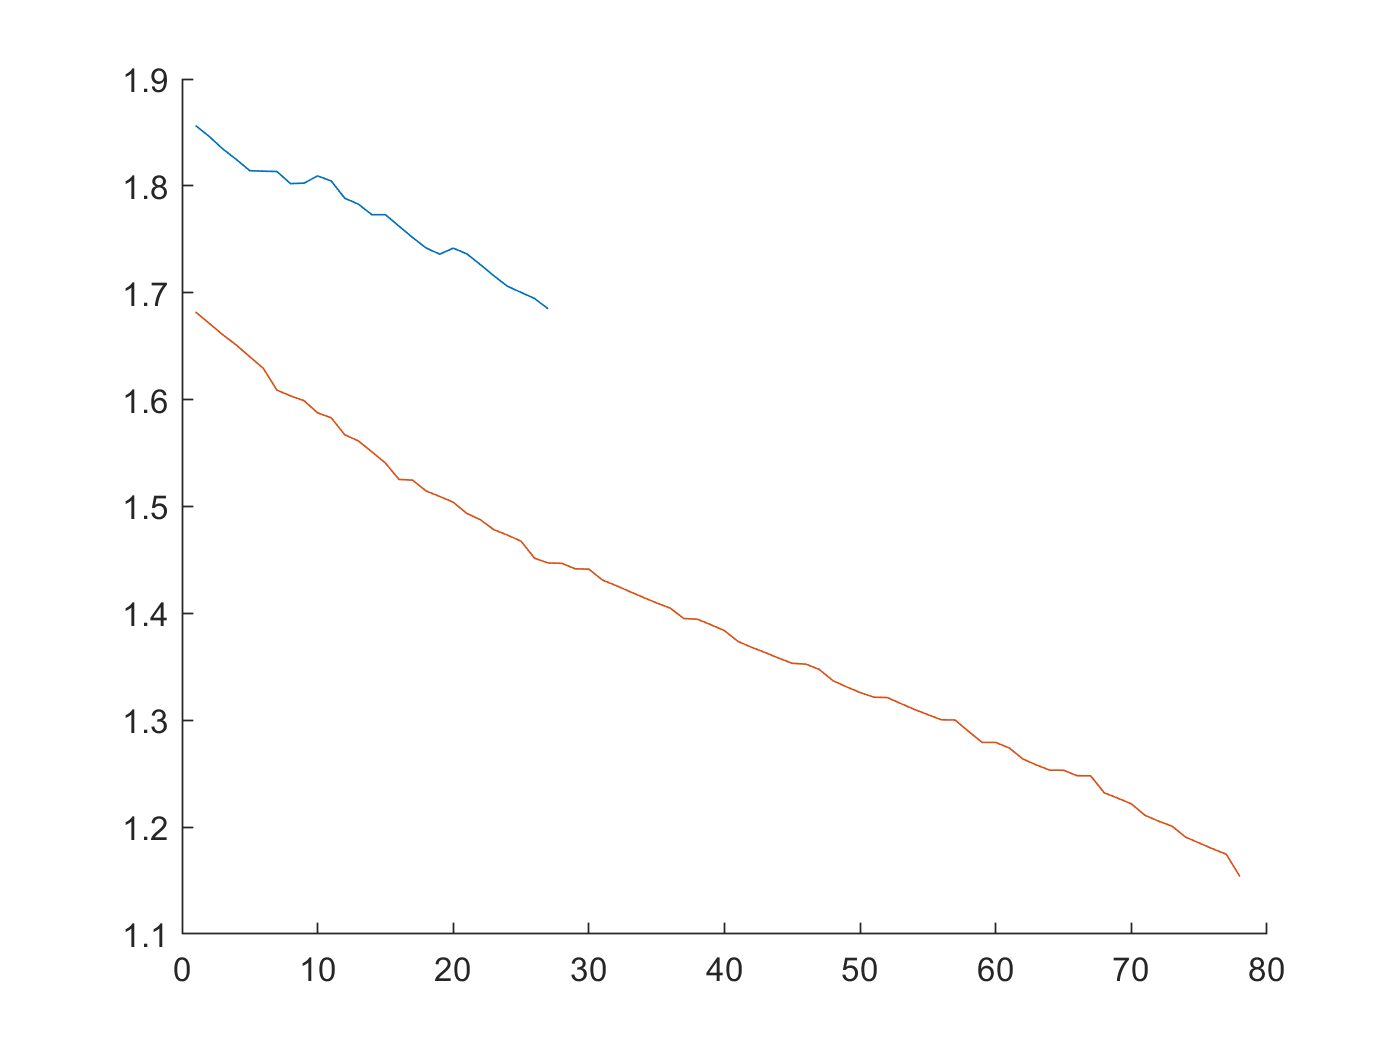

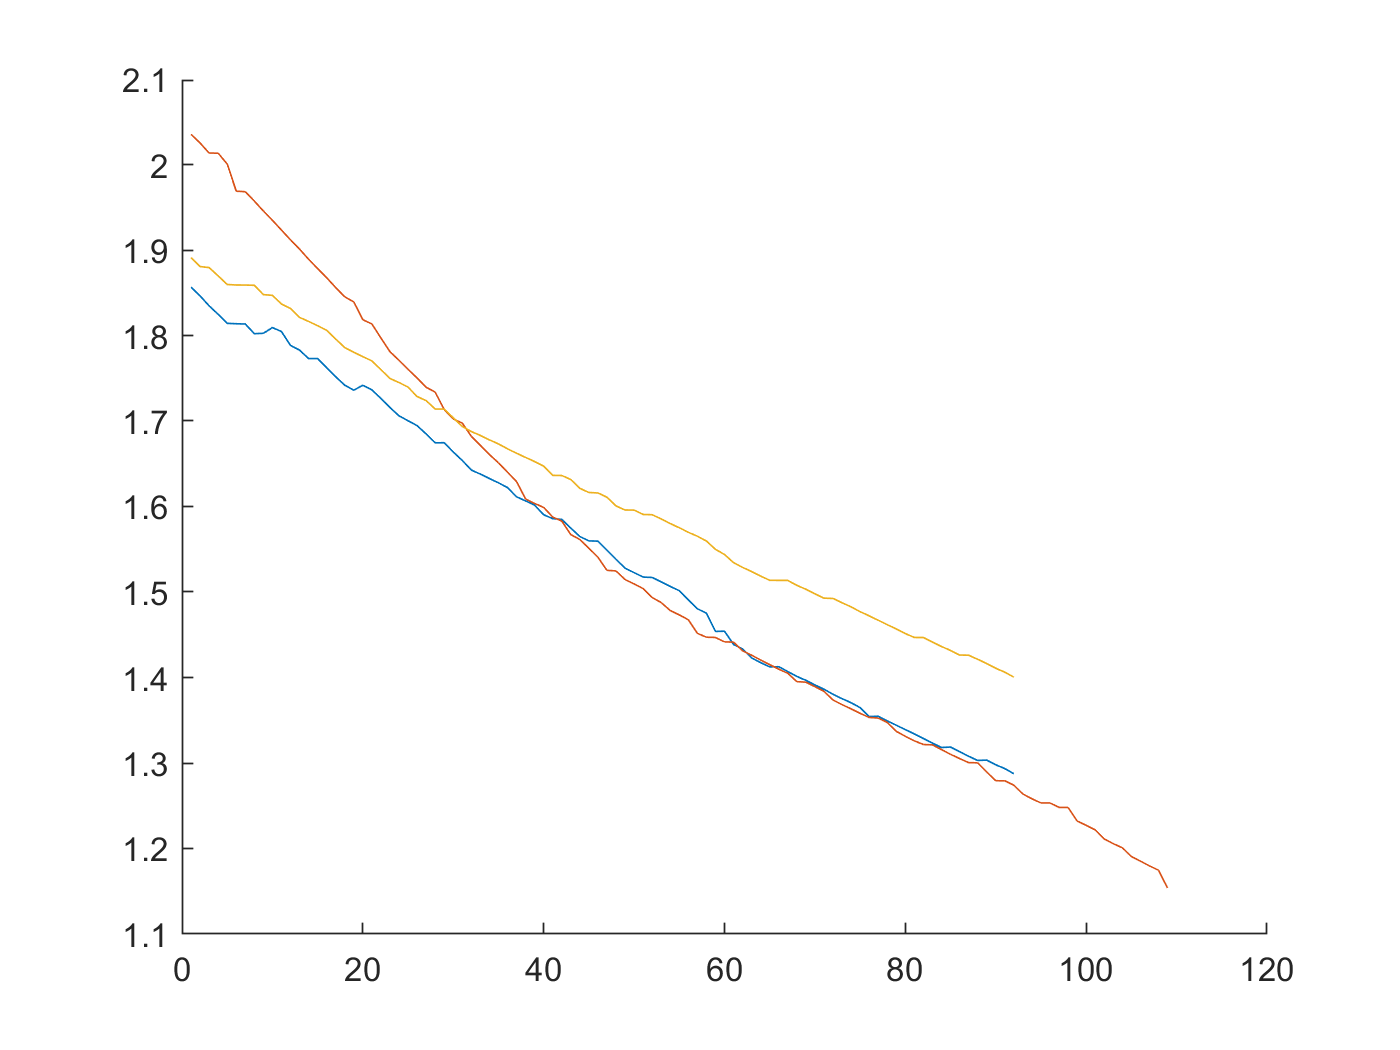

change_1v8_05 =      5
     6
     7
     8
     9
    10
    11
    12
    13


ans =     1.8142
    1.8138
    1.8134
    1.8021
    1.8026
    1.8093
    1.8046
    1.7884
    1.7829


change_1v8_06 =     20
    21
    22
    23


ans =     1.8185
    1.8135
    1.7971
    1.7810


change_1v8_07 =     14
    15
    16
    17
    18
    19


ans =     1.8165
    1.8114
    1.8061
    1.7958
    1.7859
    1.7803


change_1v7_05 =     23
    24
    25
    26
    27


ans =     1.7158
    1.7060
    1.7003
    1.6946
    1.6849


change_1v7_06 =     29
    30
    31
    32


ans =     1.7133
    1.7024
    1.6976
    1.6821


change_1v7_07 =     28
    29
    30
    31
    32
    33


ans =     1.7140
    1.7140
    1.7037
    1.6936
    1.6877
    1.6831


change_1v6_05 =     37
    38
    39
    40
    41
    42


ans =     1.6113
    1.6066
    1.6015
    1.5904
    1.5858
    1.5849


change_1v6_06 =     38
    39
    40
    41
    42


ans =     1.6088
    1.6035
    1.5990
    1.5876
    1.5830


change_1v6_07 =     45
    46
    47
    48
    49
    50
    51
    52
    53


ans =     1.6164
    1.6158
    1.6109
    1.6007
    1.5959
    1.5958
    1.5907
    1.5904
    1.5854


change_1v5_05 =     51
    52
    53
    54
    55
    56
    57


ans =     1.5175
    1.5170
    1.5119
    1.5066
    1.5015
    1.4908
    1.4804


change_1v5_06 =     49
    50
    51
    52
    53


ans =     1.5145
    1.5094
    1.5040
    1.4935
    1.4876


change_1v5_07 =     64
    65
    66
    67
    68
    69
    70
    71
    72
    73


ans =     1.5187
    1.5136
    1.5136
    1.5136
    1.5078
    1.5032
    1.4978
    1.4928
    1.4924
    1.4875


change_1v4_05 =     64
    65
    66
    67
    68
    69
    70
    71
    72


ans =     1.4174
    1.4124
    1.4126
    1.4070
    1.4012
    1.3967
    1.3913
    1.3862
    1.3804


change_1v4_06 =     65
    66
    67
    68
    69
    70
    71


ans =     1.4150
    1.4097
    1.4049
    1.3952
    1.3945
    1.3893
    1.3838


change_1v4_07 =     89
    90
    91
    92


ans =     1.4163
    1.4108
    1.4062
    1.4005


ans = 1.6946

ans = 1.6849

ans = 1.6745

ans = 1.7338

ans = 1.7133

ans = 1.7024

ans = 1.6976

ans = 1.6821

VIT_V_max = 4.2131

VIT_V_min = 3.6202

VIT_V_rate = 0.5929

VIT_I_max = 1.5141

VIT_I_min = -0.0029

VIT_I_rate = 1.5170

VIT_T_max = 30.8301

VIT_T_min = 23.0294

VIT_T_rate = 7.8006

yCap =     1.8565
    1.8463
    1.8346
    1.8248
    1.8142
    1.8138
    1.8134
    1.8021
    1.8026
    1.8093


ans =    293     1


ans = 293

cap_all =     1.8565
    1.8463
    1.8346
    1.8248
    1.8142
    1.8138
    1.8134
    1.8021
    1.8026
    1.8093


cap_all_max = 2.0353

cap_all_min = 1.1538

cap_all_rate = 1.7640

yCap_result =     0.3983
    0.3926
    0.3860
    0.3804
    0.3744
    0.3741
    0.3739
    0.3675
    0.3678
    0.3716


yPattern =     1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000


ans =    293     1


ans = 293

pattern_all =     1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000


pattern_all_max = 2

pattern_all_min = 1.5000

pattern_all_rate = 1.3333

yPattern_result =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


function [xTable, y] = helperGetFeatures(batch)
% HELPERGETFEATURES function accepts the raw measurement data and computes
% the following feature:
%
% Q_{100-10}(V) variance [DeltaQ_var]
% Q_{100-10}(V) minimum [DeltaQ_min]
% Slope of linear fit to the capacity fade curve cycles 2 to 100 [CapFadeCycle2Slope]
% Intercept of linear fit to capacity fade curve, cycles 2 to 100 [CapFadeCycle2Intercept]
% Discharge capacity at cycle 2 [Qd2]
% Average charge time over first 5 cycles [AvgChargeTime]
% Minimum Internal Resistance, cycles 2 to 100 [MinIR]
% Internal Resistance difference between cycles 2 and 100 [IRDiff2And100]

N = size(batch,2); % Number of batteries

% Preallocation of variables
y = zeros(N, 1);
DeltaQ_var = zeros(N,1);
DeltaQ_min = zeros(N,1);
CapFadeCycle2Slope = zeros(N,1);
CapFadeCycle2Intercept = zeros(N,1);
Qd2 = zeros(N,1);
AvgChargeTime = zeros(N,1);
IntegralTemp = zeros(N,1);
MinIR = zeros(N,1);

IRDiff2And100 = zeros(N,1);

for i = 1:N
    % cycle life
    y(i,1) = size(batch(i).cycles,2) + 1;
    
    % Identify cycles with time gaps
    numCycles = size(batch(i).cycles, 2);
    timeGapCycleIdx = [];
    jBadCycle = 0;
    for jCycle = 2: numCycles
        dt = diff(batch(i).cycles(jCycle).t);
        if max(dt) > 5*mean(dt)
            jBadCycle = jBadCycle + 1;
            timeGapCycleIdx(jBadCycle) = jCycle;
        end
    end
    
    % Remove cycles with time gaps
    batch(i).cycles(timeGapCycleIdx) = [];
    batch(i).summary.QDischarge(timeGapCycleIdx) = [];
    batch(i).summary.IR(timeGapCycleIdx) = [];
    batch(i).summary.chargetime(timeGapCycleIdx) = [];
    
    % compute Q_100_10 stats
    DeltaQ = batch(i).cycles(100).Qdlin - batch(i).cycles(10).Qdlin;
    DeltaQ_var(i) = log10(abs(var(DeltaQ)));
    DeltaQ_min(i) = log10(abs(min(DeltaQ)));
    
    % Slope and intercept of linear fit for capacity fade curve from cycle
    % 2 to cycle 100
    coeff2 = polyfit(batch(i).summary.cycle(2:100), batch(i).summary.QDischarge(2:100),1);
    CapFadeCycle2Slope(i) = coeff2(1);
    CapFadeCycle2Intercept(i) = coeff2(2);
    
    %  Discharge capacity at cycle 2
    Qd2(i) = batch(i).summary.QDischarge(2);
    
    % Avg charge time, first 5 cycles (2 to 6)
    AvgChargeTime(i) = mean(batch(i).summary.chargetime(2:6));
    
    % Integral of temperature from cycles 2 to 100
    tempIntT = 0;
    for jCycle = 2:100
        tempIntT = tempIntT + trapz(batch(i).cycles(jCycle).t, batch(i).cycles(jCycle).T);
    end
    IntegralTemp(i) = tempIntT;
    
    % Minimum internal resistance, cycles 2 to 100
    temp = batch(i).summary.IR(2:100);
    MinIR(i) = min(temp(temp~=0));
    IRDiff2And100(i) = batch(i).summary.IR(100) - batch(i).summary.IR(2);
end

xTable = table(DeltaQ_var, DeltaQ_min, ...
    CapFadeCycle2Slope, CapFadeCycle2Intercept,...
    Qd2, AvgChargeTime, MinIR, IRDiff2And100);

end